# Distance timings

Run all to plot 1 vs 1 million and 1 vs 1 in separate figures, with dimension on the x axis, time in nanoseconds on a logarithmic y axis, and a legend for each distance function. Measurements are read from ../infosys_measurements relative to this file.

For 1 vs 1 million, plot the mean total query times over ten runs. For 1 vs 1, plot the middle Criterion estimate or the Divan mean. Int32 is present only in the 1 vs 1 measurements.

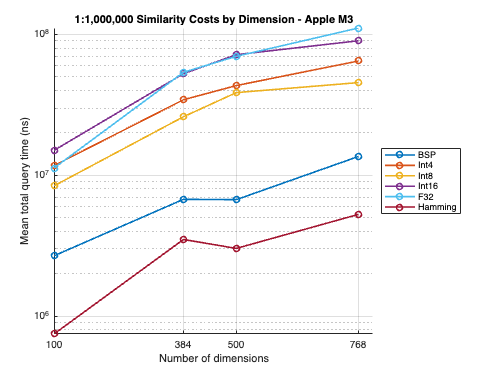

%% Distance timings on m3
% Run this script to read the current files in ../infosys_measurements and
% draw two figures. All times are converted to nanoseconds. The 1 vs 1m
% values are total query times averaged over ten runs, not per-distance times.
% For 1 vs 1, use the middle Criterion estimate and the Divan mean column.
% Int32 is included only in 1 vs 1 because 1 vs 1m has no Int32 measurements.

measurementDirectory = fullfile(fileparts(fileparts(mfilename('/Users/bc89/Documents/metric_space_rust/infosys_measurements'))), ...
    'infosys_measurements');
dimensions = [100; 384; 500; 768];
functionNames = {'BSP', 'Int4', 'Int8', 'Int16', 'Int32', 'F32', 'Hamming'};
seriesColors = lines(numel(functionNames));

%% One query against one million vectors
millionText = fileread(fullfile(measurementDirectory, 'm3_1_vs_1m.txt'));
millionTimesNs = nan(numel(dimensions), numel(functionNames));
for series = [1:4, 6:7]
    for row = 1:numel(dimensions)
        key = [functionNames{series} ' ' num2str(dimensions(row)) ':'];
        value = regexp(millionText, ...
            [regexptranslate('escape', key) '\s+([0-9.]+)'], 'tokens');
        assert(numel(value) == 1, 'Expected exactly one timing for %s.', key);
        millionTimesNs(row, series) = str2double(value{1}{1});
    end
end
oneVsMillionFigure = plotTimings(dimensions, millionTimesNs, functionNames, ...
    seriesColors, '1:1,000,000 Similarity Costs by Dimension - Apple M3', 'Mean total query time (ns)');

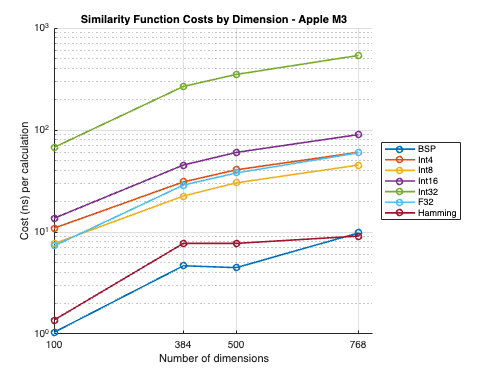


%% One vector against one vector
pairText = fileread(fullfile(measurementDirectory, 'm3_1_vs_1.txt'));
pairTimesNs = nan(numel(dimensions), numel(functionNames));
for row = 1:numel(dimensions)
    dimension = num2str(dimensions(row));

    % Divan: fastest | slowest | median | mean | samples | iters.
    divanRow = regexp(pairText, ...
        ['evp_' dimension 'dim[^\n]*\n([^\n]+)'], 'tokens');
    assert(numel(divanRow) == 1, 'Expected one Divan row for BSP/%s.', dimension);
    divanColumns = strsplit(divanRow{1}{1}, char(9474));
    assert(numel(divanColumns) >= 4, 'Missing Divan mean for BSP/%s.', dimension);
    value = regexp(divanColumns{4}, '([0-9.]+)\s+(\w+)', 'tokens', 'once');
    assert(~isempty(value), 'Invalid Divan mean for BSP/%s.', dimension);
    pairTimesNs(row, 1) = toNanoseconds(value{1}, value{2});

    % Criterion: [lower estimate, point estimate, upper estimate].
    for series = 2:5
        bits = functionNames{series}(4:end);
        key = ['bench_multiple_bit_eucs/' dimension '/' bits];
        pairTimesNs(row, series) = criterionEstimate(pairText, key);
    end
    pairTimesNs(row, 6) = criterionEstimate(pairText, ...
        ['bench_multiple_eucs/' dimension]);
    pairTimesNs(row, 7) = criterionEstimate(pairText, ...
        ['bench_multiple_one_bit/' dimension]);
end
oneVsOneFigure = plotTimings(dimensions, pairTimesNs, functionNames, ...
    seriesColors, 'Similarity Function Costs by Dimension - Apple M3', 'Cost (ns) per calculation');


%% Local functions
function value = criterionEstimate(text, key)
    pattern = [regexptranslate('escape', key) ...
        '\s+time:\s+\[\S+\s+\S+\s+([0-9.]+)\s+(\w+)\s+'];
    match = regexp(text, pattern, 'tokens');
    assert(numel(match) == 1, 'Expected exactly one Criterion timing for %s.', key);
    value = toNanoseconds(match{1}{1}, match{1}{2});
end

function value = toNanoseconds(number, unit)
    switch unit
        case 'ps'
            factor = 1e-3;
        case 'ns'
            factor = 1;
        case 'us'
            factor = 1e3;
        case 'ms'
            factor = 1e6;
        case 's'
            factor = 1e9;
        otherwise
            error('Unsupported timing unit: %s.', unit);
    end
    value = str2double(number) * factor;
end

function fig = plotTimings(dimensions, timings, names, colors, titleText, yLabel)
    fig = figure('Name', titleText, 'NumberTitle', 'off', 'Color', 'w');
    ax = axes(fig);
    hold(ax, 'on');
    for series = 1:numel(names)
        values = timings(:, series);
        if all(isnan(values))
            continue
        end
        assert(all(isfinite(values) & values > 0), ...
            'Expected a positive timing at every dimension for %s.', names{series});
        semilogy(ax, dimensions, values, '-o', 'LineWidth', 1.6, ...
            'MarkerSize', 6, 'Color', colors(series, :), ...
            'DisplayName', names{series});
    end
    ax.YScale = 'log';
    ax.XScale = 'linear';
    ax.XTick = dimensions;
    ax.YMinorGrid = 'on';
    grid(ax, 'on');
    xlabel(ax, 'Number of dimensions');
    ylabel(ax, yLabel);
    title(ax, titleText);
    legend(ax, 'show', 'Location', 'eastoutside');
    hold(ax, 'off');
end
